# matlab 预测电池寿命程序代码循环寿命

预测使用机器学习 这项研究基于斯坦福大学学生的工作，题为“容量退化前电池循环寿命的数据驱动预测”。 他们创建了一个数据集，这是同类中最大的开源，并使用机器学习来预测锂离子电池寿命。

本文通过循环对12Ah的锂电池进行充电和放电的实验,从而获得充放电的数据,实验过程按照充电后搁置一段时间,然后放电,继续搁置一段时间后充电,不停循环后,电池容量不断衰减,直到SOH值降至0.8。

充电机制为0.5C恒流充电,直到单体电压上升到3.65V,再进行恒压充电至充满。

实验中每隔1s进行一次锂电池的电流、电压、能量、容量、内阻等各项的数据记录。

1.锂电池剩余使用寿命是指在一定充放电过程后，电池的 **最大可用容量 **衰减到某一规定的失效阈值所需充放电循环数

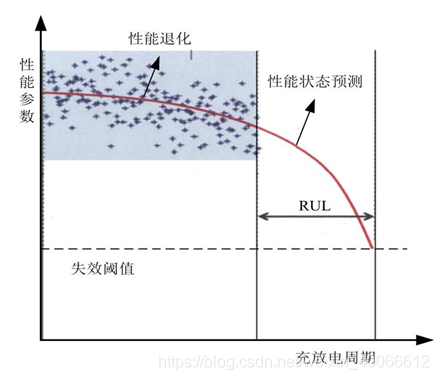

我们简单的可以看成一个**时间序列预测**的问题，比如知道前100个点，预测接下来68个点，从已知的点中提取出特征用来反映容量的变化趋势，

我们的目标是在知道的数据尽可能少的情况下，使预测[精度](https://so.csdn.net/so/search?q=%E7%B2%BE%E5%BA%A6&spm=1001.2101.3001.7020)尽可能高，**最好一次充放电循环你就知道你的电池还能循环多少次(当然这是不可能的)。**

当然还有很多可以考虑的地方，我们为了简单起见，使用的是容量数据进行预测，真正用来预测的，应该是我们根据充放电电流电压提取的**健康因子**，因为锂电池的容量是不好测得。

健康因子  factors 有很多会影响电池寿命的因素

可以从很多的方向提取，比如充放电电流，电压，温度，mvf，ic特征曲线等

2. 概述为了避免锂离子电池退化引起的事故，准确的电池寿命预测值有助于正确判断电池的老化程度，预测电池的健康工作时间，从而设计出时间充裕的最佳维护策略，从而节约资源，降低成本并确保安全。

NASA电池数据都是.mat格式的文件，可以用matlab处理，打开之后是结构类型数据，对于数据的引用其实比较简单，例如

clc,clear
load('B0018.mat');
capacity = B0018.cycle(44).data.Capacity;

`cycle中包括 充电放电和阻抗测试， 每测一次cycle的索引＋1`

`因此可以通过双循环提取你要的数据，如下`

%容量数据的提取
cyc = 0;
capacity_B18=[];
N = size(B0018.cycle,2); %319

for i = 1:N %
    if strcmp(B0018.cycle(i).type, 'discharge') %放电循环里才有容量数据
        cyc = cyc +1;
        %  capacity_B18(cyc,:) = B0018.cycle(i).data.Capacity;
        cap = B0018.cycle(i).data.Capacity;
        capacity_B18 = [capacity_B18;cap];
    end
end

4块额定容量为2Ah的锂离子电池进行 连续 的 **充放电循环 **实验，

- **Charge: **以1.5V恒定电流CC模式充电，直到电压达到4.2V,再以恒定电压CV模式继续充电，直到充电电流降至20mA

- **Discharge****： **以2A恒定电流CC进行放电，直到电池的电压分别降至2.7V,2.5V，2.2V和2.5V

- **实验终止条件**： 当电池寿命终止（EOL）标准    即额定容量下降 30%（2Ahr---1.4Ahr）

直到电池达到或超过寿命极限，4块电池的容量退化曲线如下图所示：

四组电池在 **室温25 ℃ **下以不同的 **充电、放电和阻抗** 运行条件下工作；

- 充电：1.5A恒流充电到4.2V，     4.2V的恒压充电直到电流降至20mA；

- 放电：2A恒流放电，直到四块电池的电压分别降至2.7V、2.5V、2.2V和2.5V；

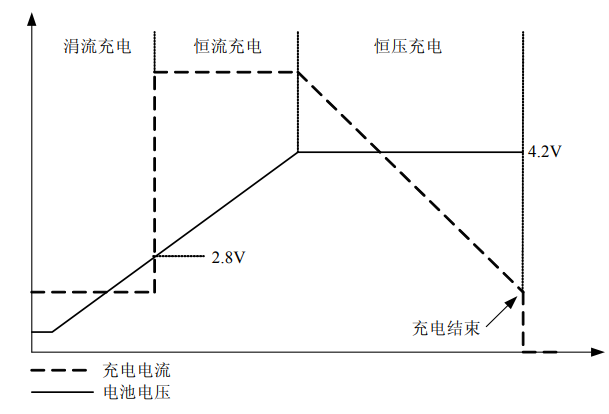

由于四组电池的实验条件不同，失效阈值分别选择为1.35Ah、1.35Ah、1.5Ah和1.45Ah；

[https://blog.csdn.net/weixin_43746824/article/details/109093495](https://blog.csdn.net/weixin_43746824/article/details/109093495)

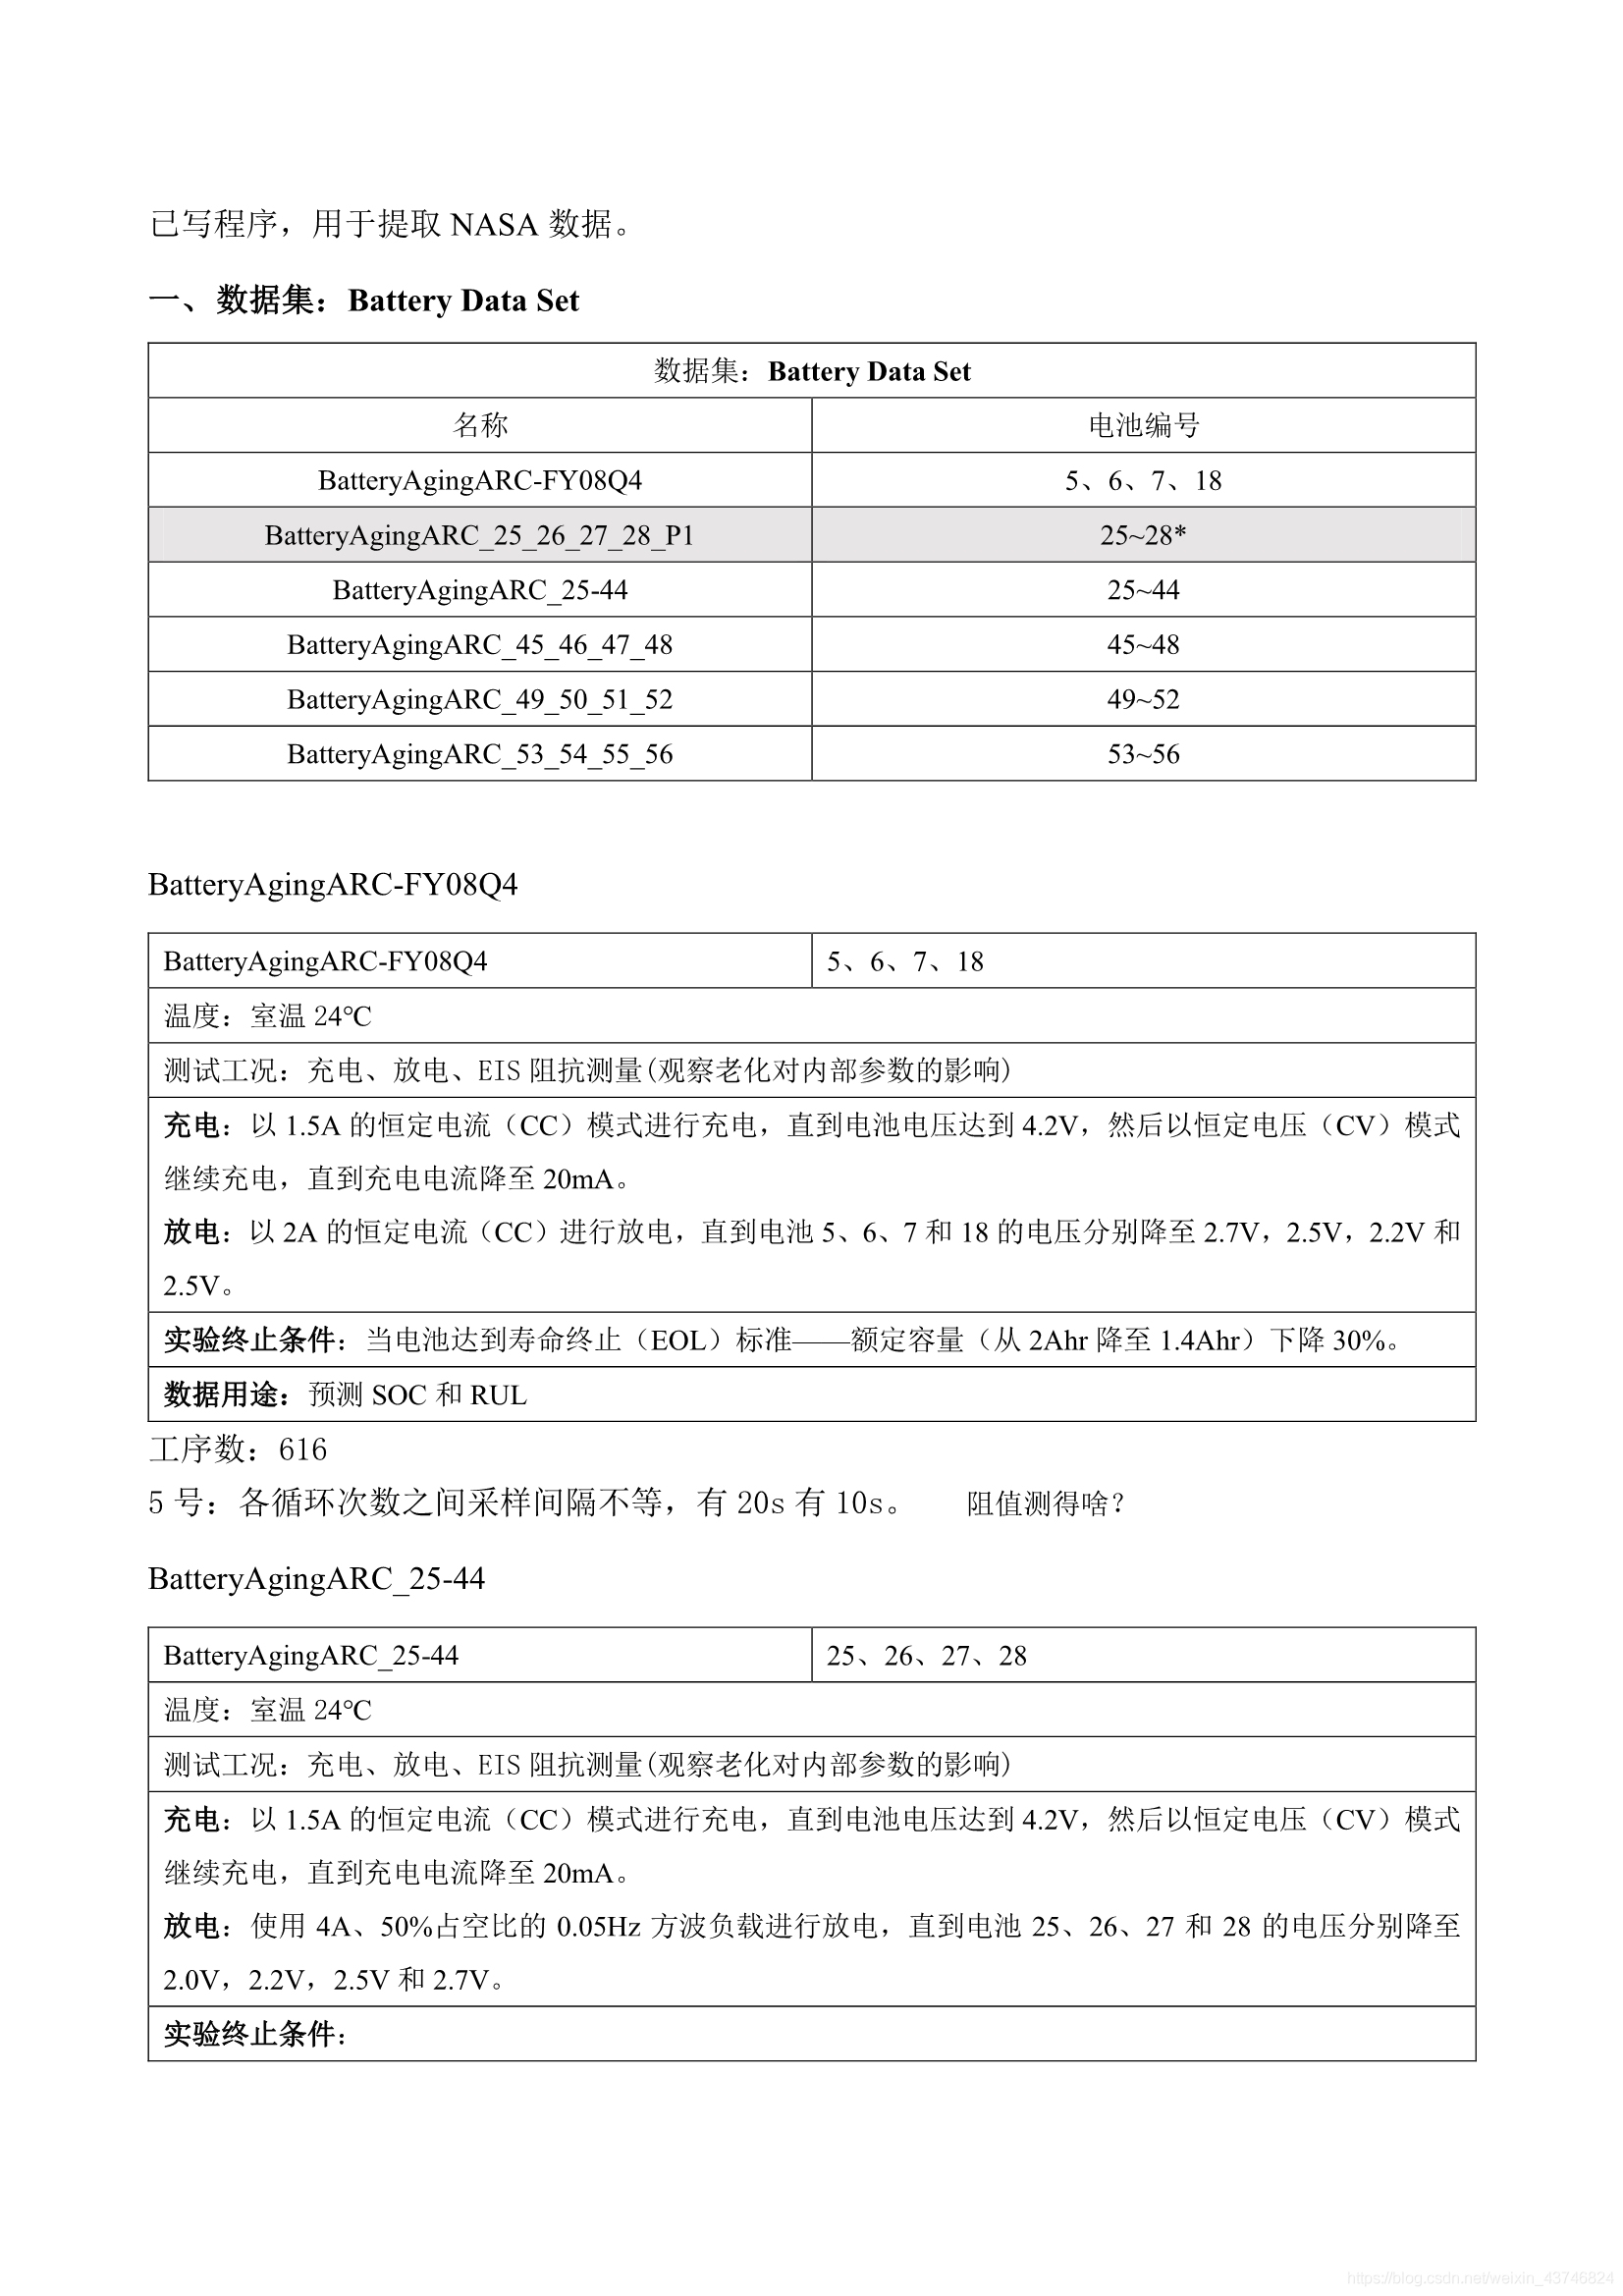

做锂电池分析，最重要的三个参数是：容量，电流和电压。

接下来，我们分别对提取它们的数据，并查看它们的变化趋势。

**容量**

锂电池寿命预测，最重要的是对放电时的电池容量衰减曲线进行建模和分析。

**电流和电压**

正如前面提到的，锂电池的测试条件如下：

充电：以 1.5A 的恒定电流（CC）模式进行充电，直到电池电压达到 4.2V，然后以恒定电压（CV）模式充电，直到充电电流降至 20mA。

放电：以 2A 的恒定电流（CC）模式进行放电，直到电池 5、6、7 和 18的电压降到 2.7V，2.5V，2.2V 和 2.5V。

# 利用MATLAB批量完成科研数据处理

https://zhuanlan.zhihu.com/p/38184872